## FIR vs. IIR Filters

What does having an infinite impulse response mean? Where does the energy come from (after the impulse has ended)?

Or is in an infinite series with a finite sum?

Let's consider an IIR filter:

y[n+1] = y[n] (or equivalently, y[n] = y[n-1]) => is this not LTI?

$Y(z) = z^{-1}Y(z)$ -- is this correct? How do we get this?

How do we get the impulse response? We can set the input to be $\delta$[n], except there is no...input?

y[n] = y[n-1] + x[n]


$$Y(z) = z^{-1}Y(z) + X(z)$$



$$\Rightarrow H(z) = \frac{Y(z)}{X(z)}= \frac{1}{1-z^{-1}}$$


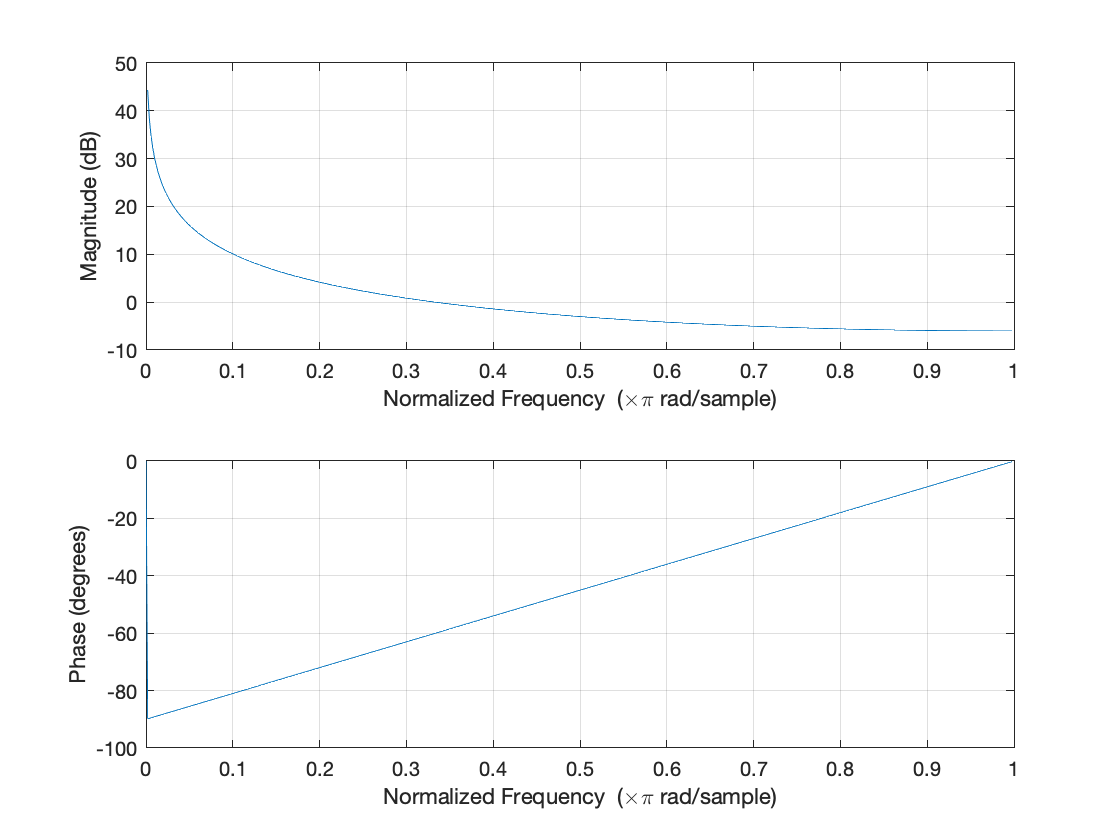

b = [1];
a = [1 -1];
freqz(b, a);

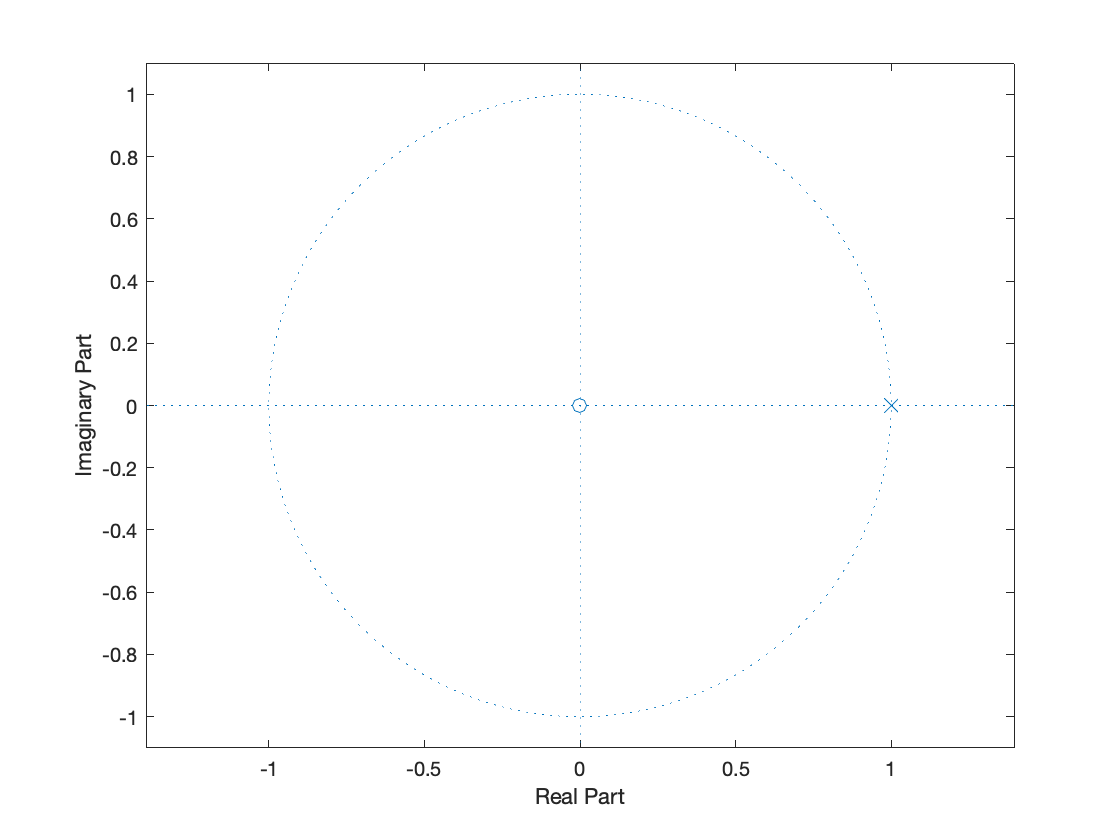

zplane(b, a);

[https://www.mathworks.com/help/signal/ref/zplane.html#mw_07f62910-abf1-4b2e-8305-ef1a3f3f7449](https://www.mathworks.com/help/signal/ref/zplane.html#mw_07f62910-abf1-4b2e-8305-ef1a3f3f7449)

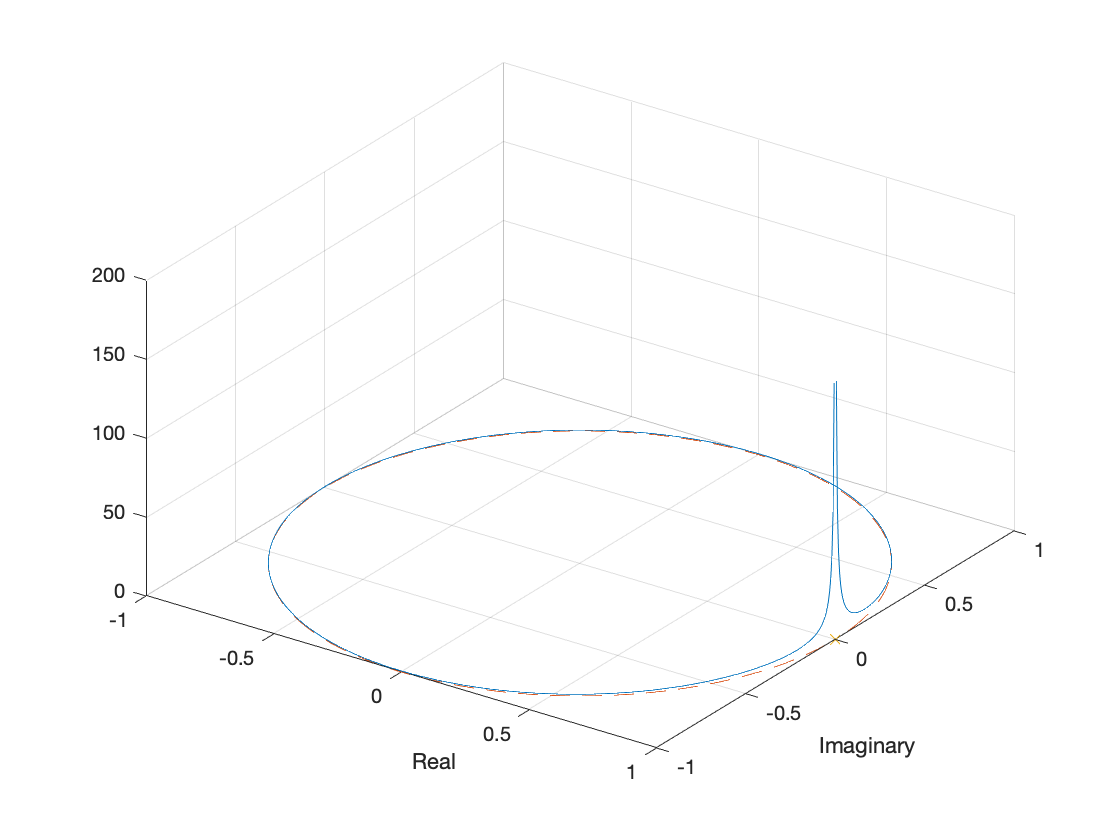

plot_zero_phase(b, a)

### Convolution


$$y[n] = (h * x)[n] = \sum_{k \in \mathbb{Z}} h[k] x[n-k]$$


Interestingly, we can substitute $k=n-k$, and then the equation becomes:


$$y[n] = (h * x)[n] = \sum_{k \in \mathbb{Z}} h[n-k] x[k]$$


### Frequency Response

Example:


$$h[n] = \delta[n-1]$$


DTFT:


$$h*x$$



$$H(z) = z^{-1}$$


Example:


$$h[n]=\frac{1}{2}\left(\delta[n] + \delta[n-1]\right)$$


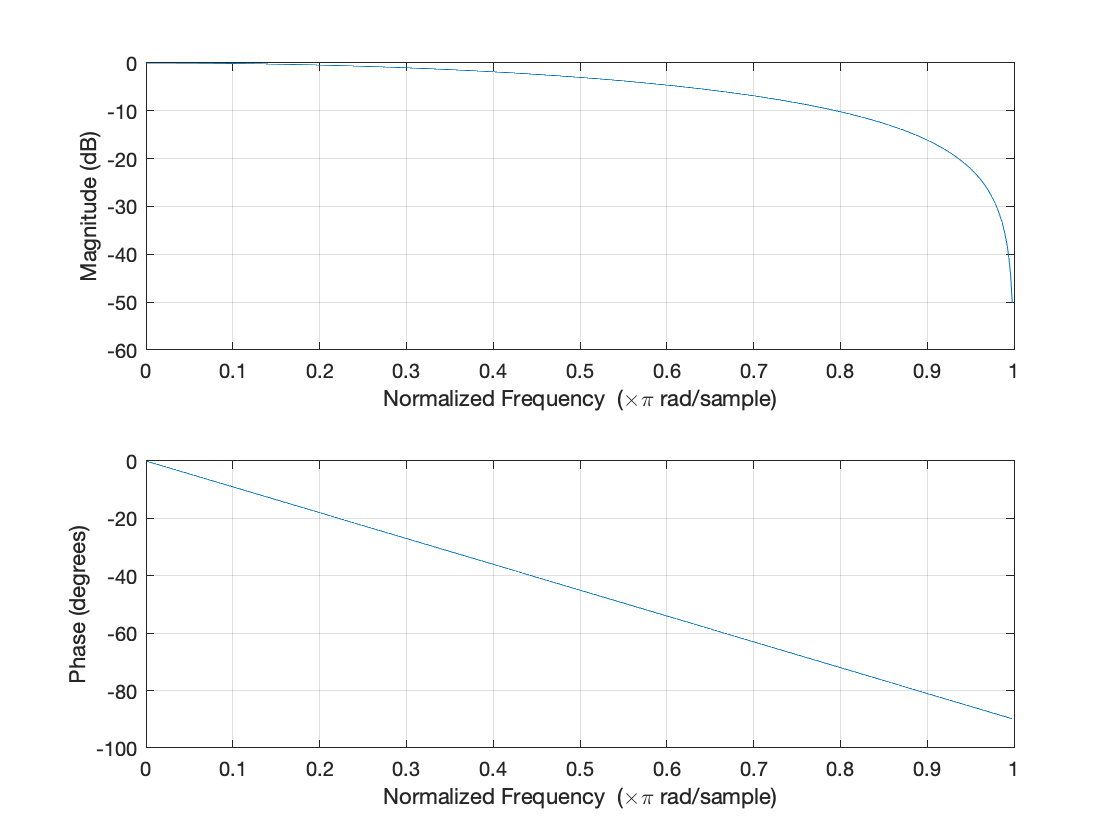

b = [0.5, 0.5];
a = [1];
freqz(b, a);

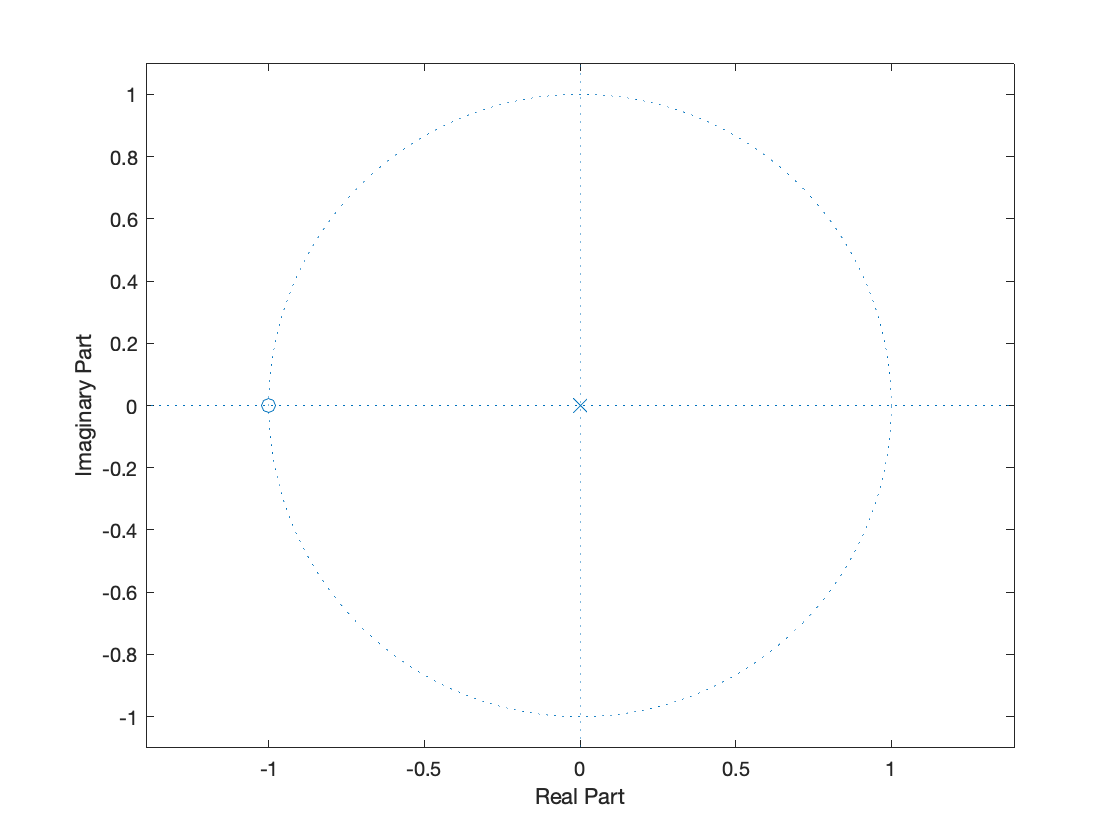

zplane(b, a);

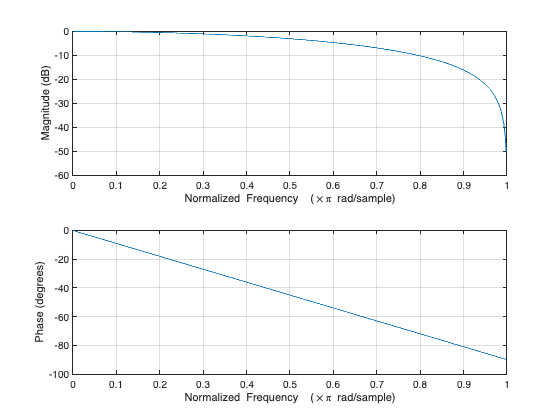

Error using ylim
When 2 input arguments are specified, the first argument must be an axes.

Error in plot_freqz (line 10)
    ylim(-360, 0)

plot_freqz(b, a)

%title(['0.5[1 + z^{-1}]']) %, 'interpreter', 'tex');

Breaking down each term:

plot_freqz([0.5], [1])
plot_freqz([0 0.5], [1])

plot_freqz([1/3], [1])
title('$\frac{1}{3} [1 + 0 + 0]$', 'interpreter', 'latex', 'FontSize', 24)

plot_freqz([0 1/3], [1])
title('$\frac{1}{3} [0 + z^{-1} + 0]$', 'interpreter', 'latex', 'FontSize', 24)

plot_freqz([0 0 1/3], [1])
title('$\frac{1}{3} [0 + 0 + z^{-2}]$', 'interpreter', 'latex', 'FontSize', 24)

plot_freqz([1/3 1/3 1/3], [1])
title('$\frac{1}{3} [1 + z^{-1} + z^{-2}]$', 'interpreter', 'latex', 'FontSize', 24)

Set $x[n] = e^{j \omega n}$, then


$$y[n]=h*x \\
= \sum_{k \in \mathbb{Z}} h[k]e^{j \omega (n-k)} \\
=  e^{j \omega n} \sum_{k \in \mathbb{Z}} h[k]e^{-j \omega k}$$


Complex exponentials are *eigenfunctions* of LTI systems.

### Z-Transform

[https://lpsa.swarthmore.edu/ZXform/FwdZXform/FwdZXform.html](https://lpsa.swarthmore.edu/ZXform/FwdZXform/FwdZXform.html) 


$$z=re^{j\omega}$$



$$X(z) = \sum_{n \in \mathbb{Z}}x[n]z^{-n}, z\in \mathbb{C}$$


Z-transform of the delta function:


$$h[n]=\delta[n] \\
\Rightarrow H(z) = \sum_{n=-\infty}^{\infty} \delta[n] z^{-n} \\
\Rightarrow H(z) = \sum_{n=-\infty}^{-1} \delta[n] z^{-n} + \sum_{n=0}^{0} \delta[n] z^{-n} + \sum_{n=0}^{-1} \delta[n] z^{-n} \\
\Rightarrow H(z) = 0 + \delta[0]z^{-0} + 0 \\
\Rightarrow H(z) = 1$$


Similarly, for a shifted delta:


$$h[n]=\delta[n-k] \\
\Rightarrow H(z) = \sum_{n=-\infty}^{\infty} \delta[n-k] z^{-n} \\
\Rightarrow H(z) = \delta[n-k] z^{-n} |_{n=k} \\
\Rightarrow H(z) = z^{-k}$$
